# EEE3548 Exercise #4

## [2019142047] [Jeon Minsu]

#### Q1. Generate your own radon transformation using imrorate(). Use built-in radon() to compare your results. Comment on the efficiency of your own radon transformation. Set the number of the anglular samples to 257.

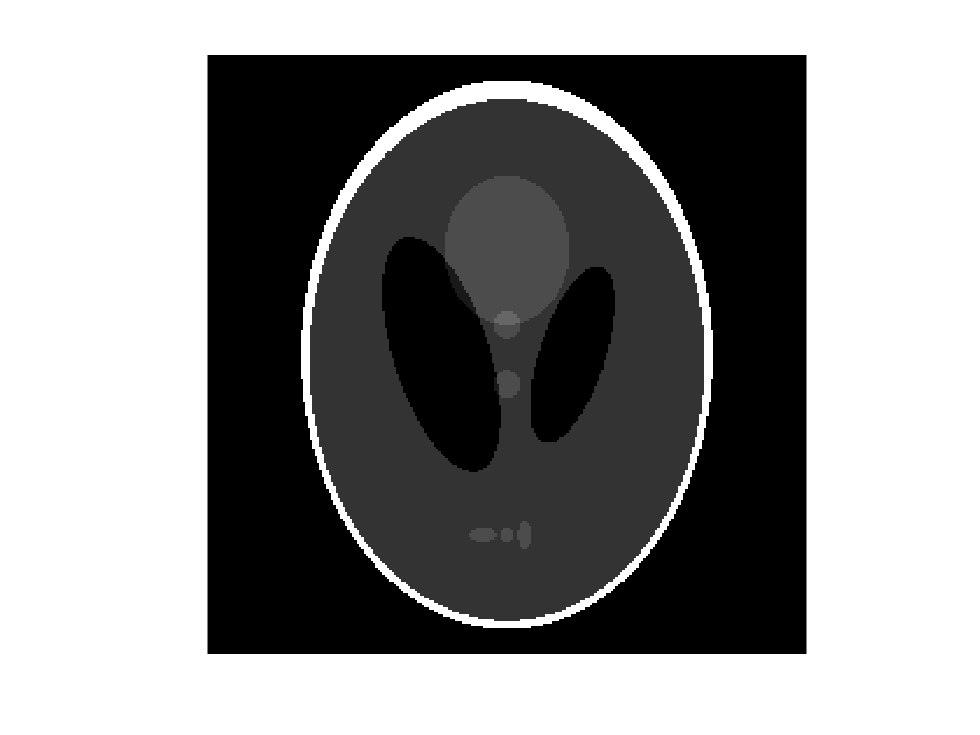

clc;
clearvars;

% use built-in phantom image
obj = phantom(257);
thetas = linspace(0, 180, 257);
dt = 5;
imagesc(obj); colormap gray; axis image; axis off;

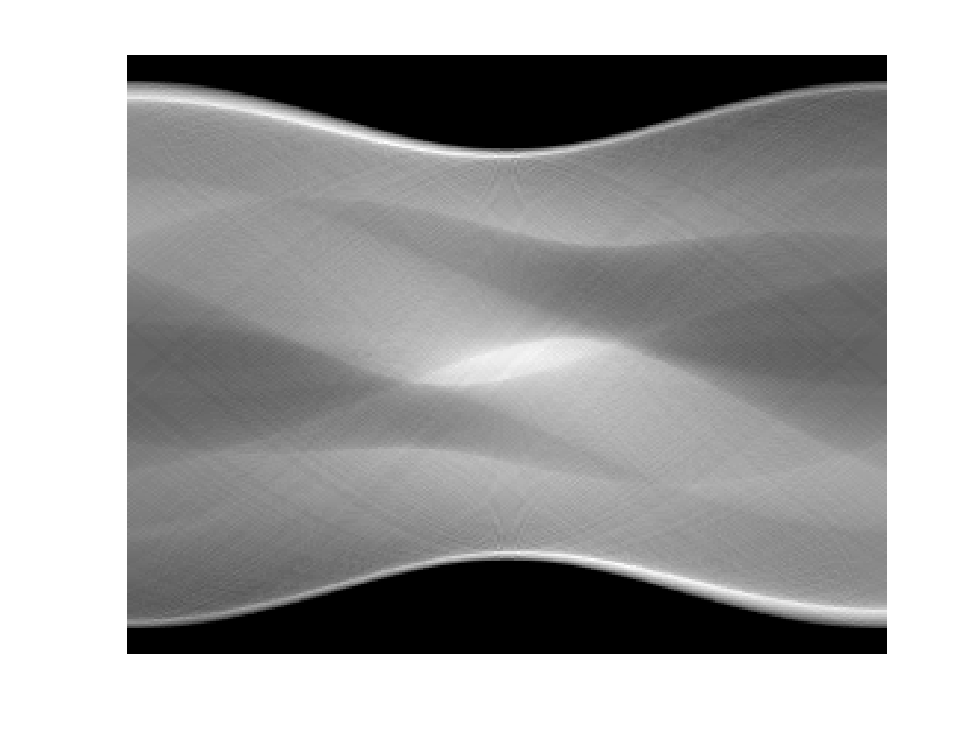


sinogram = zeros(size(obj));
for x = 1:length(thetas)
    rotate_obj = imrotate(obj, - thetas(x),'crop');     % obj을 1도씩 돌려서 
    Sum = sum(rotate_obj, 2);                           % 돌린 축을 가준으로 정사영의 합을 구함
    sinogram(:, x) = Sum;                               % theta에 따라 Sinogram에 저장
end

radon_sino = radon(obj);

imagesc(sinogram); colormap gray; axis off;

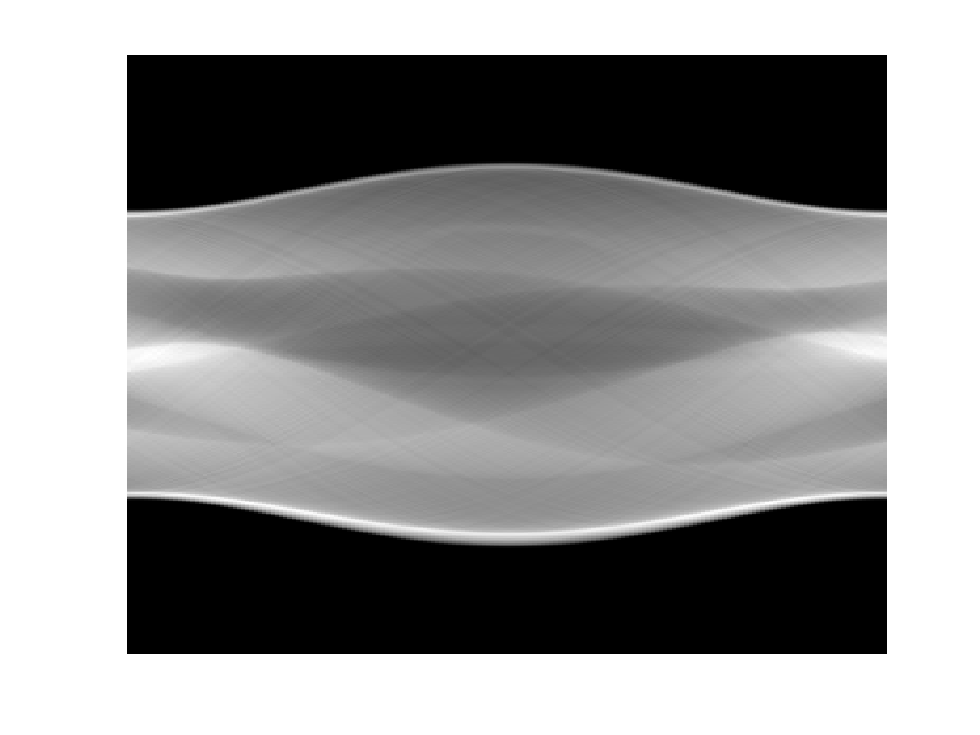

imagesc(radon_sino); colormap gray; axis off;

efficiency of my radon transformation

ㄴOwn Radon Transforamation은 Efficiency가 떨어질 수 밖에 없다. 그 이유는 Own Radon Transformation는 object를 직접 매번 조금씩 돌려서 그 값을 더해줘야하기 때문에 object의 크기에 따라 시간도 오래걸리고 비효율적이다.

이에 비해 Built-In Radon은 Radon Transform의 Coordinate 돌리는 방식을 그대로 활용하기 때문에, object의 크기에 그나마 덜영향을 받게 되고 더 효율적인 방식이라고 할수 있다.

실제로,  수행하는데 걸리는 시간을 구해보면, Built-in Radon의 수행 시간이 훨씬 더 적게 걸리는 것을 확인할 수 있다.

tic
sinogram = zeros(size(obj));
for x = 1:length(thetas)
    rotate_obj = imrotate(obj, - thetas(x),'crop');    
    Sum = sum(rotate_obj, 2);                           
    sinogram(:, x) = Sum;                              
end
toc

경과 시간은 0.073500초입니다.


tic
radon_sino = radon(obj);
toc

경과 시간은 0.018198초입니다.


#### Q2. From the sinogram, generate a reconstruction image using backprojection algorithm. Use imrotate function.

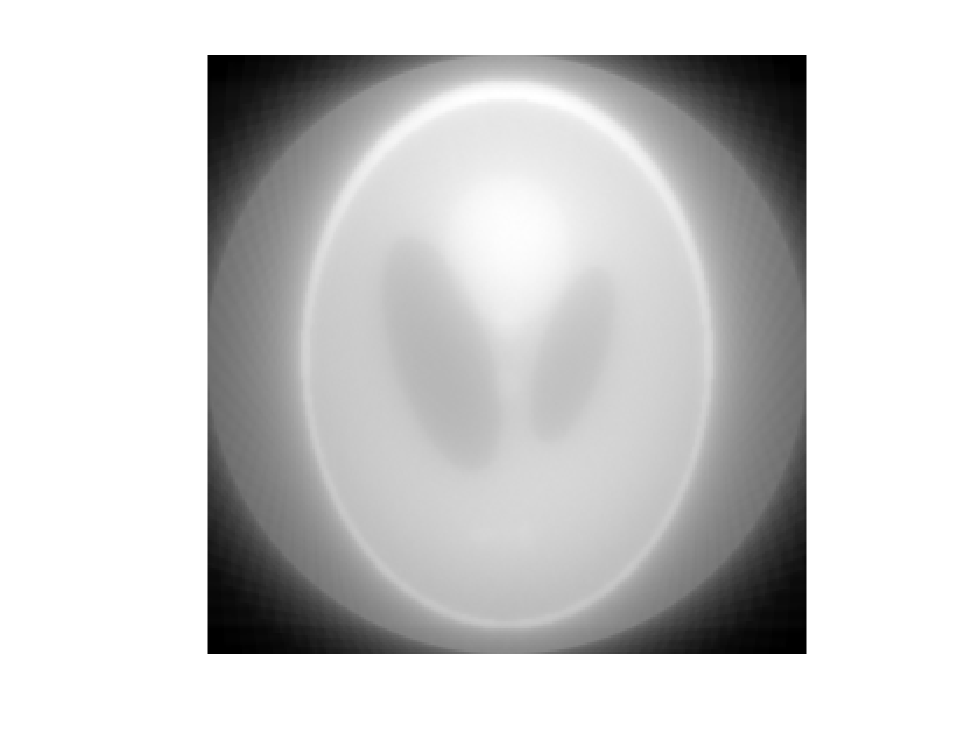

backproj = zeros(size(sinogram));                                   % backprojection size 정의

for x = 1:dt:length(thetas)
    lin = sinogram(:,x);                                            % sinogram 한 줄 가져오기
    repeat = repmat(lin,[1 length(sinogram)]);                      % sinogram 한 줄 복사
    rotate = imrotate(repeat, thetas(x), 'bilinear', 'crop');       % 배열을 dt도씩 돌려서 
    backproj =  backproj + rotate;                                  % backprojection에 저장
end
 
imagesc(backproj); colormap gray; axis image; axis off;             % backprojection 출력

#### Q3. Implement the Fourier method. From the sinograms, fill in the Fourier spectrum of the object according to the central slice theorem, and then take an inverse Fourier transform to get the reconstructed image.

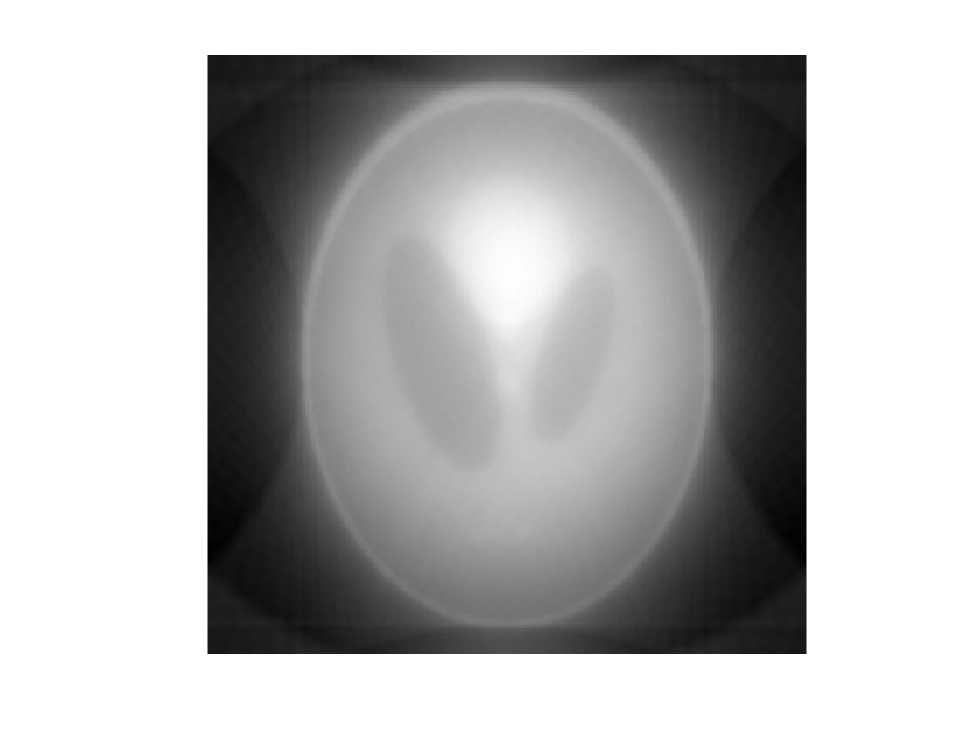

fft_recon = zeros(size(sinogram));

for x = 1:dt:length(thetas)
    fft_sinogram = fftshift(fft(ifftshift(sinogram(:,x))));     % sinogram 한줄을 1D FFT 실행
    center = (length(fft_recon) + 1) / 2;                       % 중심 찾기 위한 식
    rotate = zeros(size(sinogram));                             % imrotate를 위해 size 다시 정의
    rotate(:,center) = fft_sinogram;                            % 2D 중심 부분에 1D FFT sinogram 저장
    rotate = imrotate(rotate, thetas(x), 'bilinear','crop');    % 2D를 돌리면서 1D FFT sinogram를 dt도 간격으로 회전
    fft_recon = fft_recon + rotate;                             % 회전한 것을 계속 더해줌

end

recon = fftshift(ifft2(ifftshift(fft_recon)));                  % fft_recon를 2D Inverse FFT 실행
imagesc(real(recon));colormap gray; axis image; axis off;       % recon를 출력

#### Q4. Filter each projection with a ramp filter and implement the filtered backprojection algorithm. (Hint: Use the real part of the filtered projection.) 

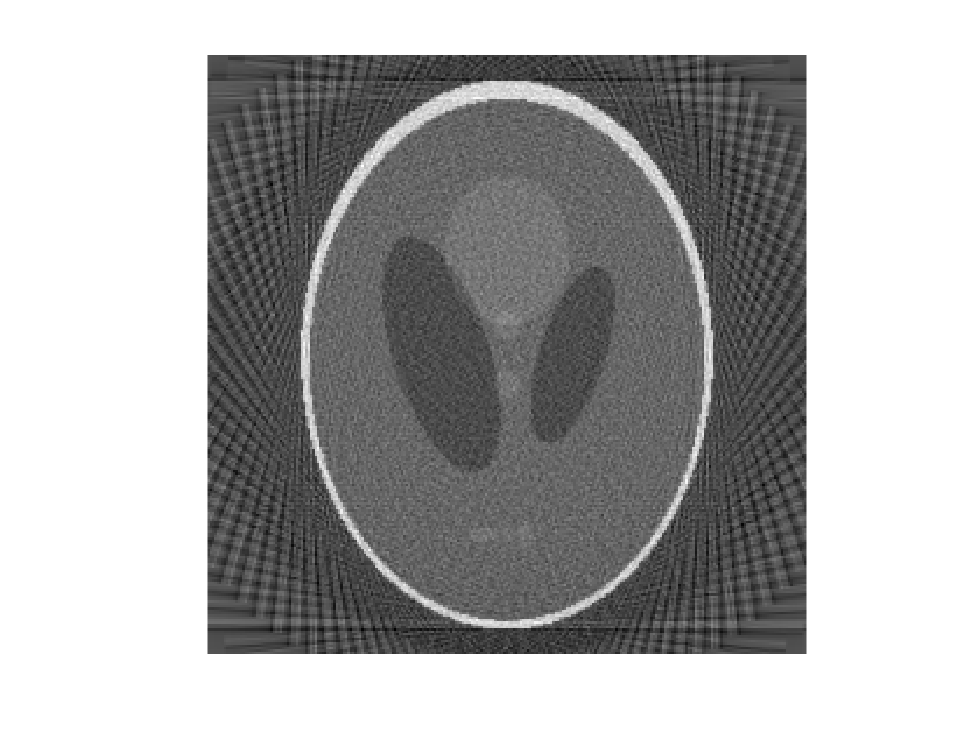

ramp = abs(linspace(-(length(obj) + 1) / 2, (length(obj) + 1) / 2, length(obj)).'); % Ramp Filter 생성
backproj = zeros(size(sinogram));

for x = 1:dt:length(thetas)
    fft_sinogram = fftshift(fft(sinogram(:,x)));                   % Convolution을 위해 sinogram을 1D FFT 실행
    sinogramfiltered = (ifft(ifftshift(fft_sinogram.*ramp)));      % Ramp Filter로 Sinogram Filtering하고 다시 1D IFFT 실행
    repeat = repmat(sinogramfiltered,[1 257]);                     % Filtering된 sinogram 한 줄 복사
    rotate = imrotate(repeat, thetas(x),'bilinear','crop');        % 배열을 dt도씩 돌려서 
    backproj =  backproj + rotate;                                 % backprojection에 저장

end     

imagesc(real(backproj)); colormap gray; axis image; axis off;      % backprojection 출력

#### Q5. Implement the Filtered Fourier method with ramp filter. 

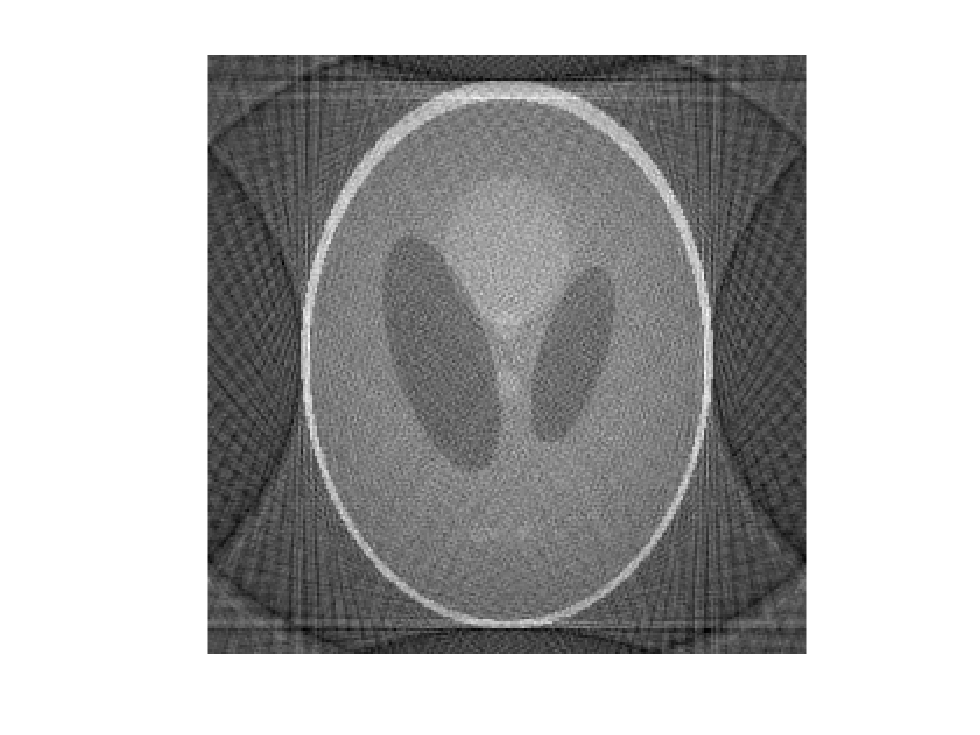

ramp = abs(linspace(-(length(obj) + 1) / 2, (length(obj) + 1) / 2, length(obj)).'); % Ramp Filter 생성

for x = 1:dt:length(thetas)
    lin = fftshift(fft(ifftshift(sinogram(:,x))));              % sinogram 한줄을 1D FFT 실행
    center = (length(fft_recon) + 1) / 2;                       % 중심 찾기 위한 식
    rotate = zeros(size(sinogram));                             % imrotate를 위해 size 다시 정의
    rotate(:,center) = lin.*ramp;                       % 2D 중심 부분에 1D FFT sinogram 저장, 이때, Ramp Filter로 Filtering
    rotate = imrotate(rotate, thetas(x), 'bilinear','crop');    % 2D를 돌리면서 1D FFT sinogram를 dt도 간격으로 회전
    fft_recon = fft_recon + rotate;                             % 회전한 것을 계속 더해줌

end

recon = fftshift(ifft2(ifftshift(fft_recon)));                  % fft_recon를 2D Inverse FFT 실행
imagesc(real(recon));colormap gray; axis image; axis off;       % recon를 출력